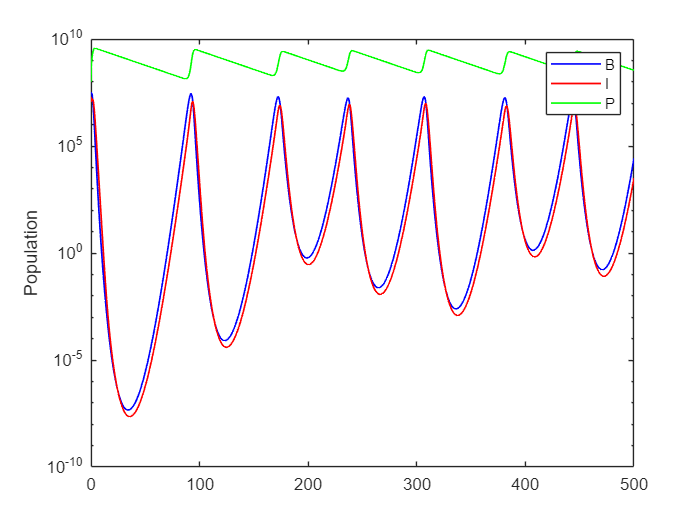

% ========================================================================
% Stochastic Bacteria-Phage Dynamics with Noisy Carrying Capacity
% ========================================================================
%   - Models logistic growth with a time-varying, stochastically fluctuating
%     environmental carrying capacity (K) driven by environmental white noise.
%   - Uses the Euler-Maruyama method for numerical integration.
%   - Compares system behavior under noisy vs. deterministic K fluctuations.
% ========================================================================

%% 1. Define Parameters
clear; clc;
params.A = 0.4; params.f = 0.01; params.r = 1.0;
params.K0 = 1; params.a = 0.09; params.Omega = 50;
params.alpha = 2; params.delta = 0.04;
sigma_K = 3.0;          % Noise intensity for K
dt = 0.001;              
tspan = [0, 500];
y0 = [0.3; 0.2; 1];     

% 2. Run simulation (function now returns K time series)
[t, y, K_series] = simulate_fluctuate_SDE1(tspan, y0, dt, params, sigma_K);

% 3. Plot: Population dynamics + K time series
figure;

% --- Figure 1: Population dynamics (log scale) ---
yplot = y * 1e8;  % Apply scaling factor
plot(t, yplot(:,1), 'b', 'LineWidth', 1); hold on;
plot(t, yplot(:,2), 'r', 'LineWidth', 1);
plot(t, yplot(:,3), 'g', 'LineWidth', 1);
set(gca, 'YScale', 'log');
%xlabel('Time'); 
ylabel('Population');
legend('B', 'I', 'P', 'Location', 'northeast');
grid off; box on;

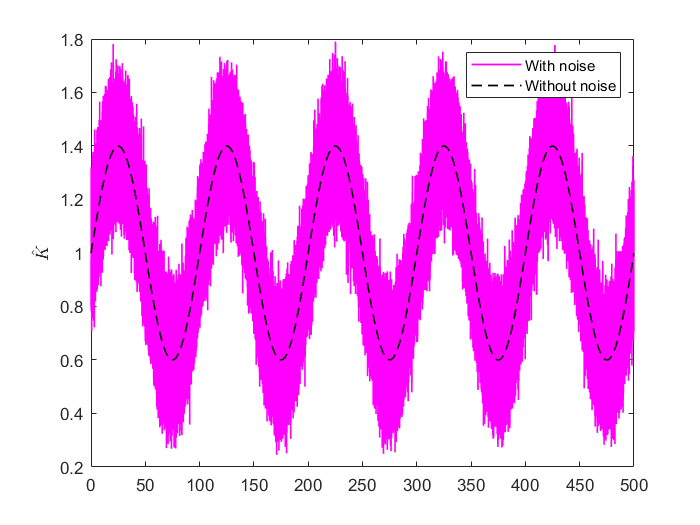


% --- Figure 2: Time series of carrying capacity K ---
figure;
plot(t, K_series, 'm', 'LineWidth', 1, 'DisplayName', 'With noise');
K_det = params.A * params.K0 * sin(2*pi*t*params.f) + params.K0;
hold on;
plot(t, K_det, 'k--', 'LineWidth', 1.0, 'DisplayName', 'Without noise');
ylabel('$\hat{K}$','Interpreter', 'latex');
legend('Location', 'northeast');
grid off; box on;

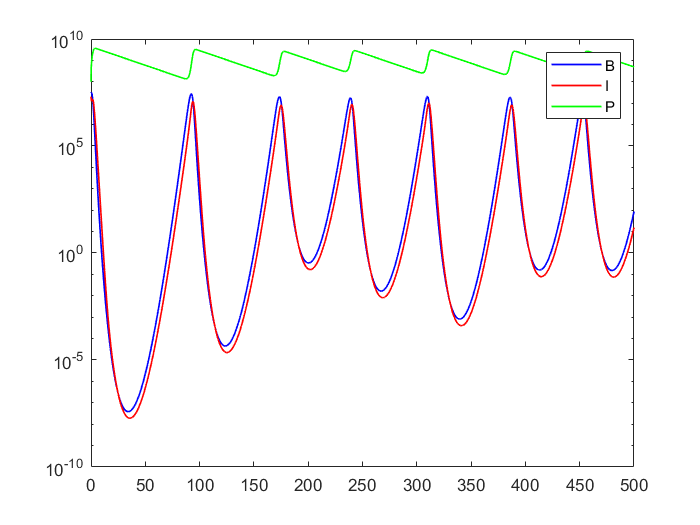


% Deterministic case (no noise)
[t, y, K_series] = simulate_fluctuate_SDE1(tspan, y0, dt, params, 0);

% Plot: Population dynamics
figure;

% --- Figure 3: Population dynamics (log scale) ---
yplot = y * 1e8;  % Apply scaling factor
plot(t, yplot(:,1), 'b', 'LineWidth', 1); hold on;
plot(t, yplot(:,2), 'r', 'LineWidth', 1);
plot(t, yplot(:,3), 'g', 'LineWidth', 1);
set(gca, 'YScale', 'log');
%xlabel('Time');
% ylabel('Population');
legend('B', 'I', 'P', 'Location', 'northeast');
grid off; box on;



%% ==================== SDE Simulation Function ====================

function [t, y, K_series] = simulate_fluctuate_SDE1(tspan, y0, dt, params, sigma_K)
    t = tspan(1):dt:tspan(2);
    N = length(t);
    y = zeros(N, 3);
    K_series = zeros(N, 1);  % Initialize array to store K at each step
    y(1,:) = y0';
    
    rng('shuffle'); 
    
    for i = 1:N-1
        B = y(i,1); I = y(i,2); P = y(i,3);
        
        % 1. Deterministic periodic component
        K_det = params.A * params.K0 * sin(2*pi*t(i)*params.f) + params.K0;
        
        % 2. Add environmental white noise
        dW = randn * sqrt(dt); 
        K = K_det + sigma_K * dW;
        K = max(K, 1e-20);  % Prevent K <= 0
        
        % 3. Store current K
        K_series(i) = K;
        
        % 4. Calculate drift terms
        N_pop = I + B;
        dBdt = params.r * (1 - N_pop/K) * B - params.a * B * P;
        dIdt = params.a * B * P - params.alpha * I;
        dPdt = params.Omega * params.alpha * I - params.a * B * P - params.delta * P;
        
        % 5. Euler-Maruyama update
        y(i+1,1) = y(i,1) + dBdt * dt;
        y(i+1,2) = y(i,2) + dIdt * dt;
        y(i+1,3) = y(i,3) + dPdt * dt;
        
        % Optional: Prevent negative populations due to numerical errors
        y(i+1,:) = max(y(i+1,:), 0);
    end
    % Compute K for the final time point (loop only runs to N-1)
    K_det_end = params.A * params.K0 * sin(2*pi*t(end)*params.f) + params.K0;
    K_series(end) = max(K_det_end + sigma_K * randn * sqrt(dt), 1e-6);
end